# Mass Spring System

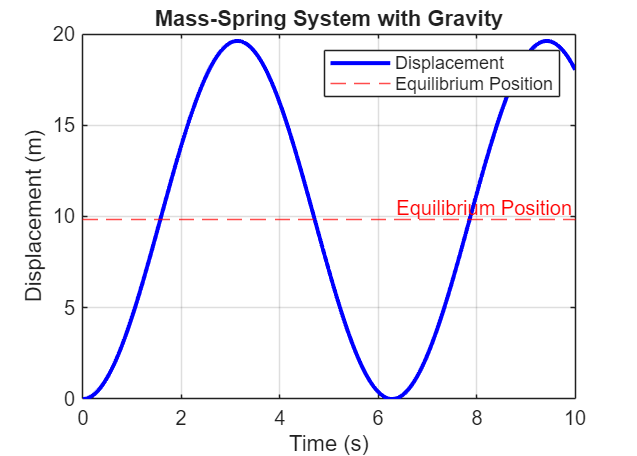

%{
ES115: Mass-Spring System
Author: Jack O'charek
Date: 4-28-26
Purpose:
    To model how an object weighing 10 kg interacts with a spring of an
    undetermined elasticity
Input: Spring constant
Output:
    Plot showing the relationship between object displacement over time
Engineering Algorithms:
    Clear screen and delete all variables
    Define constants
    Establish user input (if else for positivity)
    Establish initial conditions
    Define time metrics
    Find derived values
    Input displacement equation
    Plot displacement versus time graph
%}
clc;
clear;
close all;

m = 10;        
g = 9.81;      

k = input('Enter spring constant k (N/m): ');

if isempty(k) || k <= 0
    error('Spring constant must be a positive number.');
end

x0 = 0;        
v0 = 0;        

t = linspace(0, 10, 500);

omega = sqrt(k/m);
x_eq = (m * g) / k;   

x = x_eq + (x0 - x_eq) * cos(omega * t);

figure('Position', [300, 100, 700, 500]);

plot(t, x, 'b', 'LineWidth', 2); hold on;
yline(x_eq, '--r', 'Equilibrium Position');

xlabel('Time (s)');
ylabel('Displacement (m)');
title('Mass-Spring System');
legend('Displacement','Equilibrium Position');
grid on;